# Linear Control Design II - Group Work Problem Module 13 Solution


$$\matrix{\text{Roberto\,Galeazzi,\,Dimitros\,Papageorgiou\,\&\,Andreas\,S.\,Pedersen} \cr
\text{Technical\,University\,of\,Denmark} \cr
\text{September,\,2014} \cr
\text{Thomas\,Paulsen} \cr
\text{September,\,2017}}$$


## Description

Consider the airplane model (MIMO model).

% System matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =    -0.0558   -0.9968    0.0802    0.0415
    0.5980   -0.1150   -0.0318         0
   -3.0500    0.3880   -0.4650         0
         0    0.0805    1.0000         0


B = [0.00729 1e-5; -0.475 0.123; 0.153 1.063; 0 0]

B =     0.0073    0.0000
   -0.4750    0.1230
    0.1530    1.0630
         0         0


C = [0 1 0 0;0 0 0 1]

C =      0     1     0     0
     0     0     0     1


D = [0 0;0 0];

**Problem 1**

Is the system observable? Is it detectable?

**Solution****:**

% Check observability
rank(obsv(A,C))

ans = 4

**Problem 2**

In a former module a multivariable state feedback controller for the aircraft was designed. The closed-loop continuous eigenvalues were:


$$\lambda=\left\{\matrix{-0.5\cr-0.6\cr-0.5\pm0.5j}$$


Design a discrete time observer for the system and use the sampling period $Ts=0.1\text{s}$. Find the observer gain matrix **L** that assigns the eigenvalues of the estimation error dynamics to be 4-5 times faster than those of the closed-loop system (in continuous time). Use the Matlab function *place()* and remember that an observer can be designed by solving the dual problem of controller design.

Check the eigenvalues of the estimation error.

**Solution****:**

We discretize the system using *c2d()*:


$$\textbf{F}=\left[\matrix{0.9902&-0.0990&0.0082&0.0041\cr0.0600&0.9958&-0.0029&0.0001\cr-0.2956&0.0528&0.9533&-0.0006\cr-0.0147&0.0104&0.0977&1.0000}\right]$$



$$\textbf{G}=\left[\matrix{0.0031&-0.0002\cr-0.0474&0.0121\cr0.0137&0.1041\cr0.0005&0.0053}\right]$$


In the solution we use eigenvalues 5 times faster than the closed-loop system.


$$\lambda_d=\text{e}^{5\lambda_{cl}Ts}$$


The observer-gain is found in matlab


$$\textbf{L}=\textit{place}(\textbf{F}^T,\textbf{C}^T,\lambda_d)^T=\left[\matrix{0.1476&-0.4685\cr0.3162&-0.1297\cr-0.3285&1.3029\cr-0.0251&0.5943}\right]$$


% Discrete system
Ts = 0.1;
[F,G] = c2d(A,B,Ts);

% Observer design
lambda = [-0.5 -0.6 -0.5+0.5i -0.5-0.5i];
P_obsv_d = exp(5*lambda*Ts);

L = place(F',C',P_obsv_d)'

L =     0.1476   -0.4695
    0.3055   -0.1293
   -0.3282    1.3050
   -0.0252    0.5947



log(eig(F-L*C))/Ts

ans =   -2.5000 + 2.5000i
  -2.5000 - 2.5000i
  -2.5000 + 0.0000i
  -3.0000 + 0.0000i


**Problem 3**

Add the observer to the open loop Simulink model of the aircraft and carry out a simulation with the function on Figure 1 at both inputs, but one at a time. Plot the states, the state estimates and the estimation error.

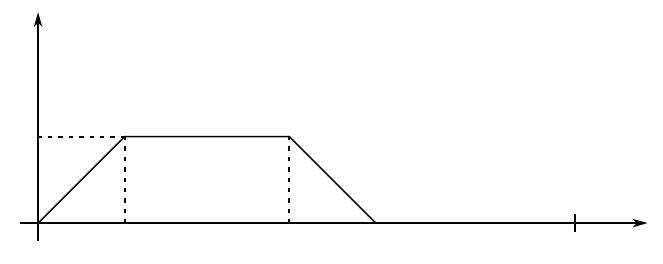


$$Figure\,1: Input\,signal\,for\,the\,closed\,loop\,system.$$


**Solution****:**

The simulink implementation of the discrete-time full-order observer can be seen in Figure 2.

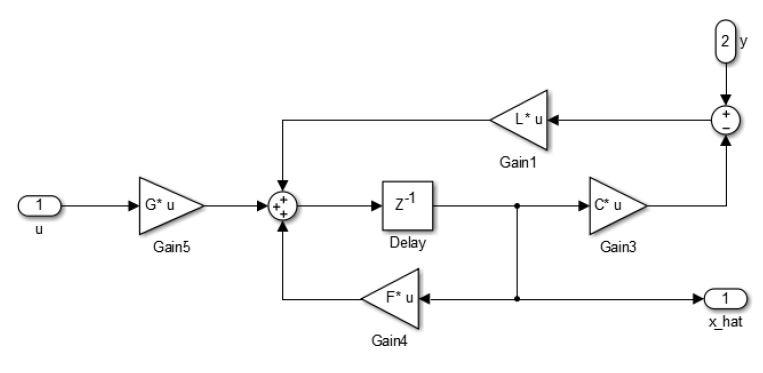


$$Figure\,2: Full\,order\,observer$$


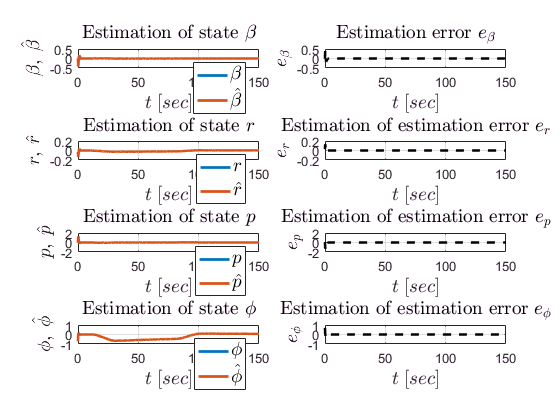

%% Simulation
t=0:.1:150;
t1=0:.1:5;
r1=.0175*t1/5;
r3=.0175*(4-(t1+15)/5);
ra=[zeros(800,1)' r1 .0175*ones(99,1)' r3 zeros(1,500)];
r=[zeros(1,100) r1 .0175*ones(99,1)' r3 zeros(800,1)' zeros(1,400)];
inp = [t' r' ra'];

%x0 = -[0.015;-0.03;-0.08;-0.7];
%x_esht_0 = [0.015;-0.03;-0.08;-0.7];
x0 = [0;0;0;0];
x_esht_0 = [0.015;-0.03;-0.08;-0.7];

sim('obsvOpenLoopSimul');

%% Plots
t = states.time;
figure
plot(t,states.signals.values(:,[1,5]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\beta, \; \hat{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\beta$', '$\hat{\beta}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\beta$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,1), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation error $e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,states.signals.values(:,[2,6]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$r, \; \hat{r}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$r$', '$\hat{r}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $r$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,2), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,states.signals.values(:,[3,7]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$p, \; \hat{p}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$p$', '$\hat{p}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $p$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,3), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,states.signals.values(:,[4,8]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\phi, \; \hat{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\phi$', '$\hat{\phi}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\phi$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,4), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

**Problem 4**

Add the discrete controller designed in the former module to the Simulink model and instead of using the true states of the system, use their estimates provided by the observer. Carry out simulations and plot the states, the state estimates, the estimation error, the outputs and the control signals. Compare the performance of the closed-loop systems with and without the observer.

**Solution****:**

The simulink implementation of the closed-loop system can be seen in Figure 3.

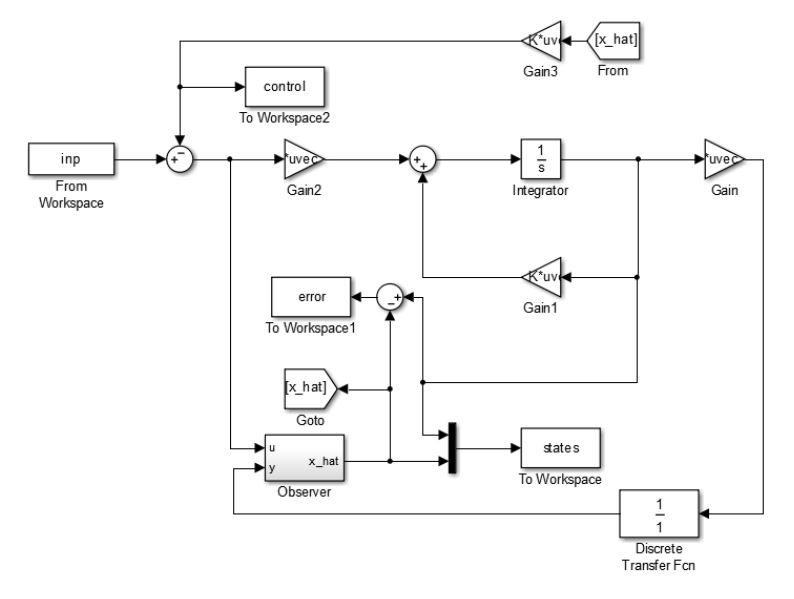


$$Figure\,3: Observer\,full-state\,feedback\,controller.$$


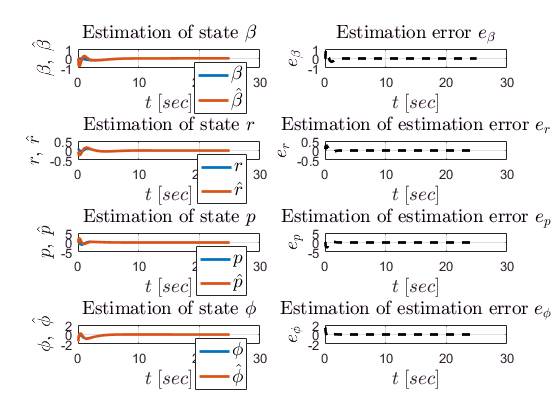

%% Simulation
t=0:.1:150;
t1=0:.1:5;
r1=.0175*t1/5;
r3=.0175*(4-(t1+15)/5);
ra=[zeros(800,1)' r1 .0175*ones(99,1)' r3 zeros(1,500)];
r=[zeros(1,100) r1 .0175*ones(99,1)' r3 zeros(800,1)' zeros(1,400)];
inp = [t' r' ra'];

% Discrete controller
ev=[-.5 -.6 -.5+1i*.5 -.5-1i*.5];
evd=exp(Ts*ev);
Kd=place(F,G,evd);

%x0 = -[0.015;-0.03;-0.08;-0.7];
%x_esht_0 = [0.015;-0.03;-0.08;-0.7];
x0 = [0;0;0;0];
x_esht_0 = [0.015;-0.03;-0.08;-0.7]*2;

sim('obsvSimul');

%% Plots
t = states.time;
figure;
plot(t,states.signals.values(:,[1,5]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\beta, \; \hat{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\beta$', '$\hat{\beta}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\beta$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,1), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation error $e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,states.signals.values(:,[2,6]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$r, \; \hat{r}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$r$', '$\hat{r}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $r$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,2), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,states.signals.values(:,[3,7]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$p, \; \hat{p}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$p$', '$\hat{p}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $p$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,3), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,states.signals.values(:,[4,8]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\phi, \; \hat{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\phi$', '$\hat{\phi}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\phi$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,4), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

**Problem 5**

Do the estimations obtained from the observer depend on how good the controller is? Can we estimate any of the states if the system is very fast or unstable?

**Solution****:**

As the controller input is also used in the observer, the estimations are independent on the controller performance. If the system is much faster than the observer, disturbance responses can be difficult to estimate.

**Problem 6**

Repeat Problem 2-4 using the controller with integral action.

**Solution****:**

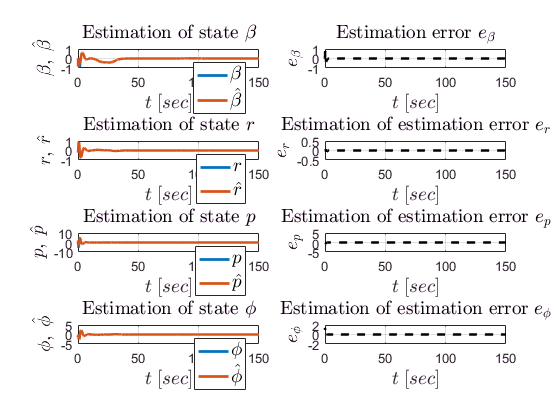

%% Integral control

% First augmenting the system with integrators
Fi=[F zeros(4,2); -C eye(2)];
Gi=[G; zeros(2,2)];
Ci=[C zeros(2,2)];

% Then designing the controllers
ev1=[-.5 -.6 -.5+1i -.5-1i -.7 -.7];
evd1=exp(ev1*Ts);
K1=place(Fi,Gi,evd1);
Kd=K1(:,1:4);
Ki=-K1(:,5:6);

% Evaluate solution
cl_eva1 = log(eig(Fi-Gi*K1))/Ts;

% Simulate
sim('obsvIntegralSimul');

%% Plots
t = states.time;
figure;
plot(t,states.signals.values(:,[1,5]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\beta, \; \hat{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\beta$', '$\hat{\beta}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\beta$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,1), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation error $e_{\beta}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,states.signals.values(:,[2,6]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$r, \; \hat{r}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$r$', '$\hat{r}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $r$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,2), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{r}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,states.signals.values(:,[3,7]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$p, \; \hat{p}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$p$', '$\hat{p}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $p$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,3), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{p}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,states.signals.values(:,[4,8]), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\phi, \; \hat{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$\phi$', '$\hat{\phi}$'}, 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of state $\phi$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,error.signals.values(:,4), '--k', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
title('Estimation of estimation error $e_{\phi}$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

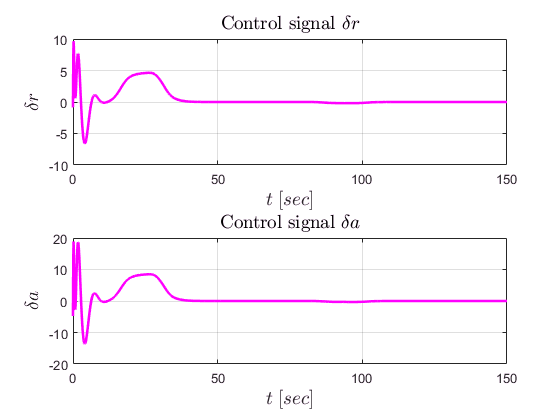


t = control.time;
figure
plot(t,control.signals.values(:,1), 'm', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\delta r$', 'Interpreter', 'latex', 'FontSize', 14);
title('Control signal $\delta r$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
figure
plot(t,control.signals.values(:,2), 'm', 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$\delta a$', 'Interpreter', 'latex', 'FontSize', 14);
title('Control signal $\delta a$', 'Interpreter', 'latex', 'FontSize', 14);
grid;